# Earthly Cloud Cover

Instructions are in the task pane to the left. Complete and submit each task one at a time. 

This code sets up the activity.

load ./data/cloudCover.mat
colormap bone

## Task 1

Each frame of the cloud cover animation has been stored in a three-dimensional array `I`, and loaded into your workspace.

[yPixels, xPixels, nFrames] = size(I);

## Task 2

To reshape an array into an M-by-N matrix, you can use the `reshape` function:

`Y` `=` `reshape``(``X``,``M``,``N``)`

X = reshape(I, xPixels*yPixels, nFrames);

## Task 3

[U, S, V] = svd(X, "econ");

## Task 4

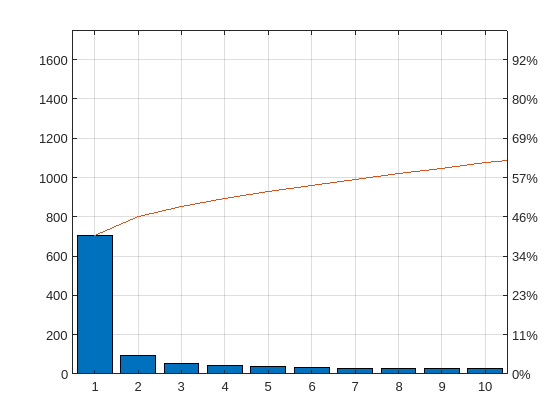

pareto(diag(S))
grid on

## Task 5

It looks like the first three singular values capture about 50% of the information contained in the frames of the animation. 

Next, you'll want to take a look at what these dominant feature look like. 

Remember, you can approximate the original matrix using a linear combination of singular values, and the first term is the largest:


$$X\approx u_1 s_1 v_1^T +u_2 s_2 v_2^T +\ldotp \ldotp \ldotp$$


sv = 1;
x = U(:, sv)*S(sv, sv)*V(:, sv)';

## Task 6

Notice that `x` is a 23328-by-45 matrix. This matrix contains the most dominant features across all frames in the animation.

In order to visualize this, you need to reshape again. You can reshape a two-dimensional array into a three-dimensional array by including a third input in the `reshape` function. 

`Y` `=` `reshape``(``X``,``M``,``N``,``L``)`

x = reshape(x, yPixels, xPixels, nFrames);

## Task 7

The first singular value encapsulates most of the cloud cover on Earth. As you can see annotated in the image below, there is a cloudy strip along the equator called the Intercontinental Convergence Zone.

Note also the less cloudy zones correspond to the locations of some of the major deserts on the Earth.

The second most dominant features across the frames are encapsulated by the second term in the linear combination:


$$X\approx u_1 s_1 v_1^T +u_2 s_2 v_2^T +\ldotp \ldotp \ldotp$$


You can use the slider to explore the dominant features across the various frames.

sv = 2;
x = U(:, sv)*S(sv, sv)*V(:, sv)';
x = reshape(x, yPixels, xPixels, nFrames);

This code visualizes the SVD approximation to a given frame of the animation.

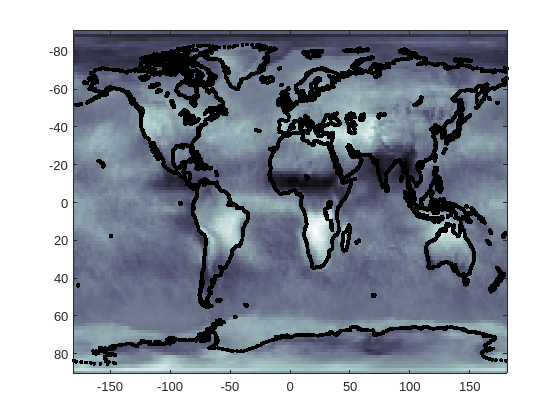

frame = 1;
imagesc(lon, lat, x(:, :, frame))
hold on
scatter(coastlon, coastlat, "k.")
hold off